# Analyzer_branchCurrents.mlx

## This file statistically analyzes the branch Currents for symptoms of Critical Slowing Down.

#### This script changes all interpretation parameters to LaTeX.

% This script changes all interpreters from tex to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'


tableName = strcat(folder_name, 'nominalValuesTable_',...
    system_name, '.csv');

nominalValuesTable = readtable(tableName);

branchesToPlot = 5;

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

T = nominalValuesTable.T

T = 15

W = nominalValuesTable.W

W = 1500


currentsArrName = strcat(folder_name,'currents_', ...
    system_name, '.mat');
currentsArr = load(currentsArrName);
currentsArr = currentsArr.currentsArr;

bifurcationIdx = size(currentsArr,1)

bifurcationIdx = 10724

indicesToPlotTruncated = 1:bifurcationIdx;
xaxisTruncated = (bifurcationIdx - indicesToPlotTruncated)...
    *sampling_rate/(60);


figure('Name', 'Detrended Fluctuation Analysis of Branch Currents');
subplot(2,2,1);
plot(xaxisTruncated, currentsArr(:, branchesToPlot));
set(gca,'xdir','reverse')
title('Currents');
xlabel('Time to Bifucation (min)');
ylabel('Currents (A)');

name_labelcurrents = strcat(folder_name, 'labelcurrents_'...
    , system_name, '.mat');
load(name_labelcurrents, "labelcurrents");
% labelcurrents = labelcurrents.labelcurrents;
legend(labelcurrents(branchesToPlot))

#### Time to smooth the current  using Gaussian Kernel Smoothing (GKS).

sigma_f = 5;
GKS = @(n, sigma_f) (1/...
    ( sqrt(2*pi) * sigma_f ))*exp(-n^2/( 2 * (sigma_f^2) ))

GKS = function_handle with value:
    @(n,sigma_f)(1/(sqrt(2*pi)*sigma_f))*exp(-n^2/(2*(sigma_f^2)))


% syms GKS_sym(n, sigma_f)
% GKS_sym(n,sigma_f) = (1/( sqrt(2*pi) * sigma_f )) * exp(-n^2/( 2 * (sigma_f^2) ))
% var = vpa(GKS_sym)
gksFilter = [];
for n = 1:W
    gksFilter(n) = GKS(n, sigma_f);
end
gksFilter = gksFilter.*(1/sum(gksFilter));
gks_currentsArr = [];
for bus = 1:size(currentsArr,2)
    gks_currentsArr(:, bus) = ...
        conv(currentsArr(:, bus), gksFilter, 'full');
end



subplot(2,2,2);
convolutionMargin = floor(bifurcationIdx*0.005)

convolutionMargin = 53

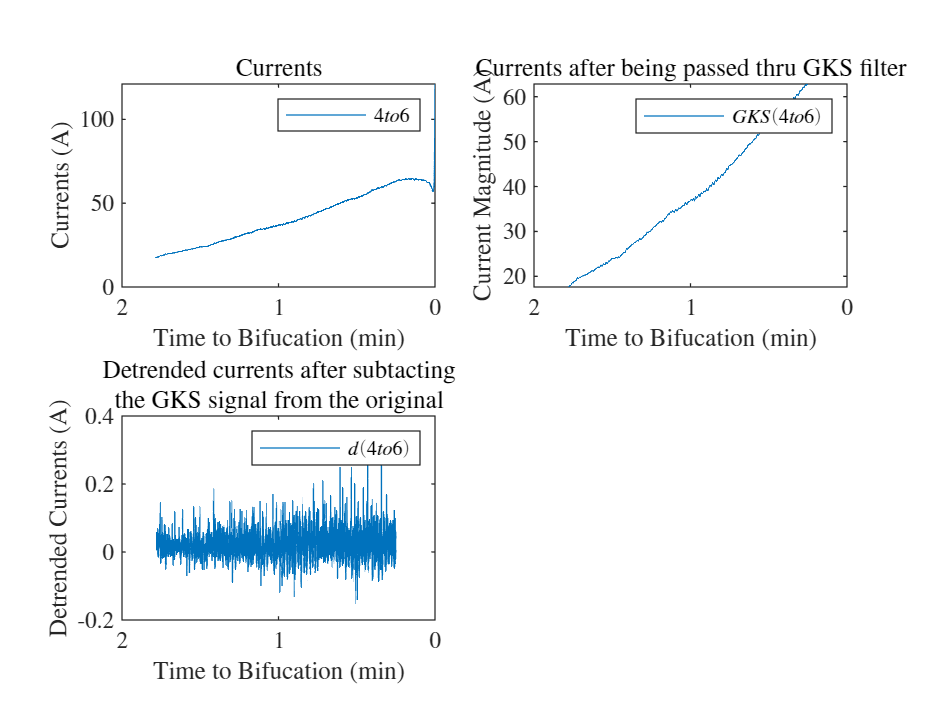

indicesToPlotPostConvolution = 1+convolutionMargin:bifurcationIdx-W+1;
xaxisPostConvolution = (bifurcationIdx - indicesToPlotPostConvolution)...
    *sampling_rate/(60);
plot(xaxisPostConvolution, ...
    gks_currentsArr(indicesToPlotPostConvolution,branchesToPlot));
set(gca,'xdir','reverse')

title('Currents after being passed thru GKS filter');
xlabel('Time to Bifucation (min)');
ylabel('Current Magnitude (A)');

name_labelGKScurrents = strcat(folder_name, 'labelGKScurrents_'...
    , system_name, '.mat');
load(name_labelGKScurrents, "labelGKScurrents");
% labelGKScurrents = labelGKScurrents.labelGKScurrents;
legend(labelGKScurrents(branchesToPlot))

subplot(2,2,3);
currentsDetrendedArr = ...
    currentsArr(indicesToPlotPostConvolution,:) -...
    gks_currentsArr(indicesToPlotPostConvolution,:);

plot(xaxisPostConvolution, ...
    currentsDetrendedArr(:, branchesToPlot));
set(gca,'xdir','reverse')
title({['Detrended currents after subtacting '] ...
    ['the GKS signal from the original']});
xlabel('Time to Bifucation (min)');
ylabel('Detrended Currents (A)');

name_labelDeltacurrents = strcat(folder_name, 'labelDeltacurrents_'...
    , system_name, '.mat');
load(name_labelDeltacurrents, "labelDeltacurrents");
% labelDeltacurrents = labelDeltacurrents.labelDeltacurrents;
legend(labelDeltacurrents(branchesToPlot))